clear all
% data=readtable("C:\Users\thoma\Downloads\book1.xlsx")
data=readtable("C:\Users\thoma\Documents\Eurostoxx.xlsx",'Sheet','Sheet2','Range','A1:G1608')

data = 1607×7 table
       Date        Open      High      Low      Close       Volume      SMAVG_15_ 
    __________    ______    ______    ______    ______    __________    __________

    05/04/2019    3445.1    3446.1    3440.3    3441.3             0           NaN
    04/04/2019    3434.3    3449.4    3425.2    3441.9    3.7192e+08    4.7233e+08
    03/04/2019    3399.9    3435.9    3399.9    3435.6    4.1543e+08    4.7874e+08
    02/04/2019    3386.2    3402.8    3382.8    3395.7     3.797e+08    4.7408e+08
    01/04/2019    3353.7      3391    3353.7    3385.4     6.986e+08    4.7086e+08
    29/03/2019    3326.4    3354.3    3326.4    3351.7    4.0559e+08    4.4616e+08
    28/03/2019    3321.3    3337.6    3315.9    3320.3     3.423e+08    4.506

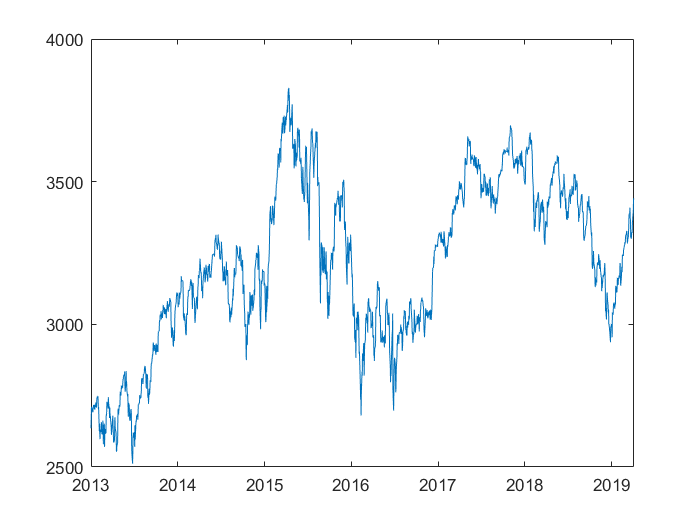



plot(data.Date,data.Close)

data=flipud(data)

data = 1607×7 table
       Date        Open      High      Low      Close       Volume      SMAVG_15_ 
    __________    ______    ______    ______    ______    __________    __________

    31/12/2012    2619.6    2638.2    2619.6    2635.9    1.0315e+08     7.003e+08
    02/01/2013    2659.8    2711.3    2659.8    2711.3    1.0315e+09    7.2357e+08
    03/01/2013    2705.8    2705.8    2689.3    2701.2    8.9775e+08    7.2366e+08
    04/01/2013    2696.9      2711    2690.1    2709.3    8.2507e+08    7.3206e+08
    07/01/2013    2712.3    2714.2      2691    2695.6    8.0569e+08    7.3419e+08
    08/01/2013    2690.9    2710.2    2684.9    2691.4    8.8352e+08     7.524e+08
    09/01/2013    2697.5    2710.5      2691    2706.4    1.0719e+09    7.868

logreturn=[nan;diff(log(data.Close))]

logreturn =        NaN
    0.0282
   -0.0037
    0.0030
   -0.0051
   -0.0015
    0.0055
    0.0007
    0.0035
   -0.0010


nanvar(logreturn)

ans = 1.1986e-04

logreturn=[nan;diff(log(data.Close))]*100

logreturn =        NaN
    2.8174
   -0.3706
    0.3005
   -0.5103
   -0.1526
    0.5536
    0.0694
    0.3509
   -0.0968


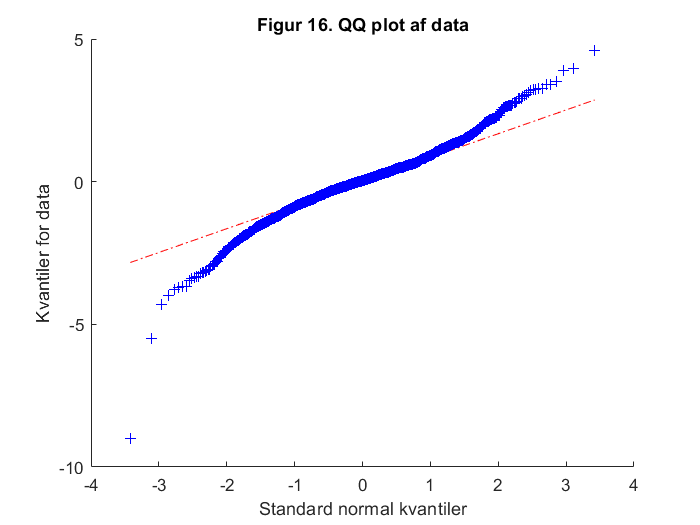


qqplot(logreturn)
title('Figur 16. QQ plot af data')
xlabel('Standard normal kvantiler')

yticks([-10,-5,0,5,10])

ylabel('Kvantiler for data')

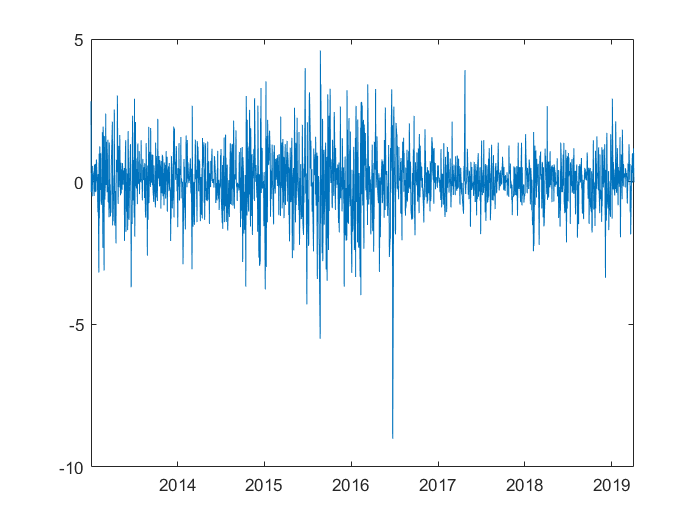


plot(data.Date,logreturn)

[h,pValue,stat,cValue]=lbqtest(logreturn,'lags',5)

h = logical
   1


pValue = 0.0044

stat = 17.0339

cValue = 11.0705

[h,pValue,stat,cValue]=lbqtest(logreturn.^2,'lags',4)

h = logical
   1


pValue = 0

stat = 119.8640

cValue = 9.4877

%Momenter
mean(logreturn(2:end))

ans = 0.0166

var(logreturn(2:end))

ans = 1.1986

skewness(logreturn(2:end))

ans = -0.4837

kurtosis(logreturn(2:end))

ans = 7.4235

%Test statistik. Normalitet
[h,p,jbstat,critval]=jbtest(logreturn)

h = 1

p = 1.0000e-03

jbstat = 1.3720e+03

critval = 5.9548